clear variables

## 3.1.1. Discretize the controller 𝐻𝑐(𝑠)=𝑘/𝑠 using tustin(bilinear) transformation.

T = 0.05; %sampling period
k = 1;
Hc = tf(k, [1 0]);
Hc_discrete = c2d(Hc, T, 'tustin')

Hc_discrete =
 
  0.025 z + 0.025
  ---------------
       z - 1
 
Sample time: 0.05 seconds
Discrete-time transfer function.



## 3.1.2. Discretize the process H_p(s) = 2400 / ((s + 20) * (s + 40)) using zero order hold method.

Hp = tf(2400, [1 60 800]);
Hp_discrete = c2d(Hp, T, 'zoh')

Hp_discrete =
 
      1.199 z + 0.441
  ------------------------
  z^2 - 0.5032 z + 0.04979
 
Sample time: 0.05 seconds
Discrete-time transfer function.



## 3.1.3. Use the zpk function to write on your notebook the open loop transfer function.

H_ol = zpk(Hc_discrete * Hp_discrete)

H_ol =
 
   0.029968 (z+1) (z+0.3679)
  ---------------------------
  (z-1) (z-0.3679) (z-0.1353)
 
Sample time: 0.05 seconds
Discrete-time zero/pole/gain model.



## 3.1.4. Analyze the stability of the closed loop system depending on ∈ (0, ∞); draw on your notebook the root locus and mention the obtained values of k directly on the graphics.

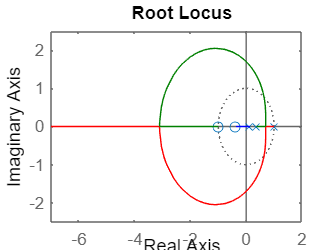

figure,
rlocus(H_ol)

% k = 9.26 -> zeta = 0

## 3.1.5. Analyze closed loop behavior depending on 𝑘∈(0,∞); use Matlab to generate the closed loop step response for all different behaviors that result depending on k; give suggestive titles to the generated plots.

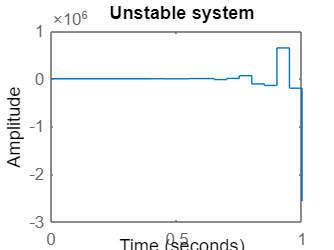

figure;
step(feedback(100*H_ol,1),1); title('Unstable system')

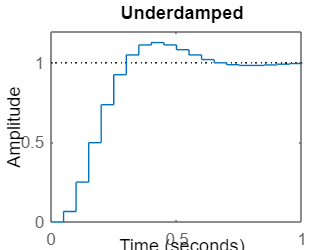

figure;
step(feedback(2.2*H_ol,1),1); title('Underdamped')

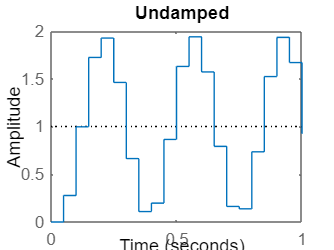

figure;
step(feedback(9.26*H_ol,1),1); title('Undamped')

## 3.1.6. Use the zgrid functionto obtain the value of k for which the overshoot of the closed loop is below 10%.

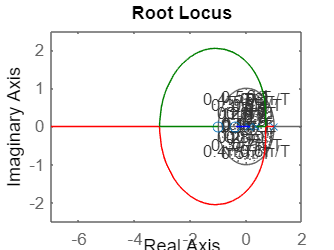

figure,
rlocus(H_ol)
zgrid